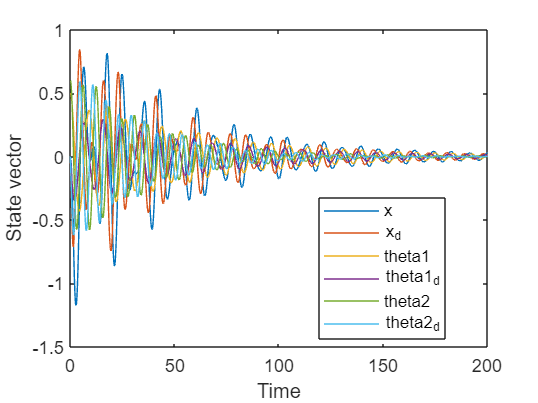

% Clear the workspace and close all figures
clc; clear; close all;

t_span = 0:0.01:1000;
% Solve the ODE and obtain the state vector
[t, x] = ode45(@nonlinear, t_span, [0; 0; 0.5; 0; 0.6; 0]);

figure;
plot(t, x(:, 1),  'DisplayName', 'x');
hold on;
plot(t, x(:, 2),  'DisplayName', 'x_d');
plot(t, x(:, 3),  'DisplayName', 'theta1');
plot(t, x(:, 4),  'DisplayName', 'theta1_d');
plot(t, x(:, 5),  'DisplayName', 'theta2');
plot(t, x(:, 6),  'DisplayName', 'theta2_d');

xlim([0, 200]);
xlabel('Time');
ylabel('State vector');
legend('Location', 'best');

As it can be seen, the result of lqr controller for both linear and nonlinear systems is similar.

%Lyapunov indirect method for stability analysis
g = 9.8;
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
A = [0 1 0 0 0 0;
        0 0 ((-g*m1)/M) 0 ((-g*m2)/M) 0;
        0 0 0 1 0 0;
        0 0 ((-g*(M+m1))/(M*l1)) 0 -((g*m2)/(M*l1)) 0;
        0 0 0 0 0 1;
        0 0 ((-g*m1)/(M*l2)) 0 ((-g*(M+m2))/(M*l2)) 0 ];

B = [0;
    (1/M);
     0;
     (1/(M*l1));
     0;
     (1/(M*l2))];

Q = 100 * eye(6);
R = 0.001;

[K,~,~] = lqr(A, B, Q, R);

e = eig(A-B*K);
disp(e);

  -0.3838 + 0.3543i
  -0.3838 - 0.3543i
  -0.0298 + 1.0342i
  -0.0298 - 1.0342i
  -0.0161 + 0.7209i
  -0.0161 - 0.7209i



As the real part of the eigenvalues of the (A-BK) matrix is in the negative half plane, the system is locally asymptotically stable.

function dx = nonlinear(t, x)
    dx = zeros(6,1);
    g = 9.8;
    M = 1000;
    m1 = 100;
    m2 = 100;
    l1 = 20;
    l2 = 10;
    
    % System matrices
    A = [0 1 0 0 0 0;
        0 0 ((-g*m1)/M) 0 ((-g*m2)/M) 0;
        0 0 0 1 0 0;
        0 0 ((-g*(M+m1))/(M*l1)) 0 -((g*m2)/(M*l1)) 0;
        0 0 0 0 0 1;
        0 0 ((-g*m1)/(M*l2)) 0 ((-g*(M+m2))/(M*l2)) 0 ];
    
    B = [0;
        (1/M);
        0;
        (1/(M*l1));
        0;
        (1/(M*l2))];

    Q = 100 * eye(6);
    R = 0.001;

    [K,~,~] = lqr(A, B, Q, R);
    F = -K*x;

    dx(1) = x(2);
    dx(2) = (-m1*g*sin(x(3))*cos(x(5)) - m2*g*sin(x(5))*cos(x(5)) - m1*l1*x(4)^2*sin(x(3))-m2*l2*x(6)^2*sin(x(5))+F)/(M+m1+m2-m1*cos(x(3))^2-m2*cos(x(5))^2);
    dx(3) = x(4);
    dx(4) = (-m1*g*sin(x(3))*cos(x(5)) - m2*g*sin(x(5))*cos(x(5)) - m1*l1*x(4)^2*sin(x(3))-m2*l2*x(6)^2*sin(x(5))+F)/(l1*(M+m1+m2-m1*cos(x(3))^2-m2*cos(x(5))^2)) - (g*sin(x(3)))/l1;
    dx(5) = x(6);
    dx(6) = (-m1*g*sin(x(3))*cos(x(5)) - m2*g*sin(x(5))*cos(x(5)) - m1*l1*x(4)^2*sin(x(3))-m2*l2*x(6)^2*sin(x(5))+F)/(l2*(M+m1+m2-m1*cos(x(3))^2-m2*cos(x(5))^2)) - (g*sin(x(5)))/l2;
    
end

